# s-curve | vertical

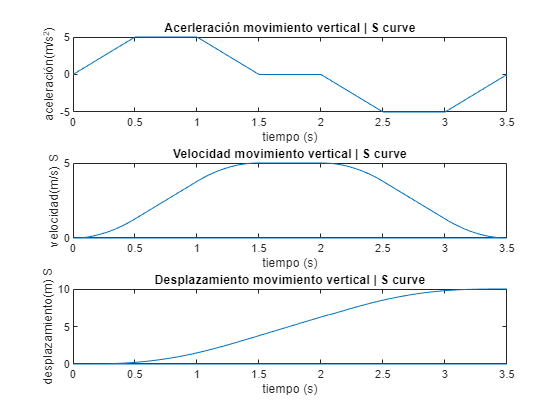

clear
delta=0.01;
m=10;
t=0:delta:3.5;
asv=(m*ctramp(t)-m*ctramp(t-3.5/7)-m*ctramp(t-2*3.5/7)).*(t<3*3.5/7)...
    +(-1)*(m*ctramp(t-4*3.5/7)-m*ctramp(t-(5*3.5/7))-m*ctramp(t-(6*3.5/7))).*(t>4*3.5/7);

subplot(3,1,1)
plot(t,asv)
title('Acerleración movimiento vertical | S curve')
xlabel('tiempo (s)')
ylabel('aceleración(m/s^2)')

vsv=zeros(length(asv));
r=0;
for i=1:length(vsv)
    index=find(t<=r);
    vsv(i) = delta*sum(asv(index));
    r=r+delta;
end
subplot(3,1,2)
plot(t,vsv)
title('Velocidad movimiento vertical | S curve')
xlabel('tiempo (s)')
ylabel('velocidad(m/s) S')

ssv=zeros(length(asv));
r=0;
for i=1:length(ssv)
    index=find(t<=r);
    ssv(i) = delta*sum(vsv(index));
    r=r+delta;
end
subplot(3,1,3)
plot(t,ssv)
title('Desplazamiento movimiento vertical | S curve')
xlabel('tiempo (s)')
ylabel('desplazamiento(m) S')


%{
Perfil de fuerza 
masa=366.7;
fdef=adef*masa+366.7*9.81;

plot(t,fdef)    
title('Perfil de fuerza')
xlabel('tiempo (s)')
ylabel('fuerza (N) S')

%Perfil de torque 
fi=masa*9.81-fdef;
torquedef=(fi+masa*9.81)*1.22;
plot(t,torquedef)
title('Perfil de torque')
xlabel('tiempo (s)')
ylabel('torque (N m) S')
%}

# trapecio

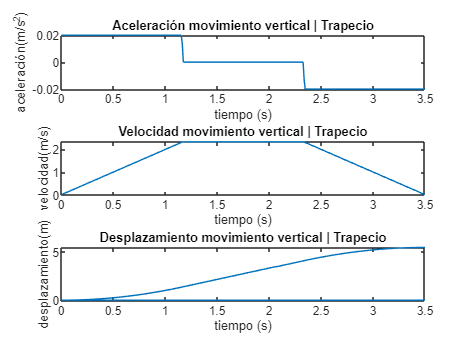

clear
delta=0.01;
m=2;
t=0:delta:3.5;
vdef=m*ctramp(t)-m*ctramp(t-3.5/3)-m*ctramp(t-2*3.5/3);
adef=diff(vdef);

ta=linspace(0,3.5,350);
subplot(3,1,1)
plot(ta,adef)
title('Aceleración movimiento vertical | Trapecio')
xlabel('tiempo (s)')
ylabel('aceleración(m/s^2)')

%v=zeros(length(a));
%r=0;
%for i=1:length(v)
%    index=find(t<=r);
%    v(i) = delta*sum(a(index));
%    r=r+delta;
%end
subplot(3,1,2)
plot(t,vdef)
title('Velocidad movimiento vertical | Trapecio')
xlabel('tiempo (s)')
ylabel('velocidad(m/s)')

sdef=zeros(length(t));
r=0;
for i=1:length(sdef)
    index=find(t<=r);
    sdef(i) = delta*sum(vdef(index));
    r=r+delta;
end
subplot(3,1,3)
plot(t,sdef)
title('Desplazamiento movimiento vertical | Trapecio')
xlabel('tiempo (s)')
ylabel('desplazamiento(m)')

# Triángulo

clear
delta=0.01;
m=2;
t=0:delta:3.5;
v=m*ctramp(t)-2*m*ctramp(t-3.5/2);
a=diff(v);
ta=linspace(0,3.5,350);
subplot(3,1,1)
plot(ta,a)
title('Aceleración movimiento vertical | Triángulo')
xlabel('tiempo (s)')
ylabel('aceleración(m/s^2)')

%v=zeros(length(a));
%r=0;
%for i=1:length(v)
%    index=find(t<=r);
%    v(i) = delta*sum(a(index));
%    r=r+delta;
%end
subplot(3,1,2)
plot(t,v)
title('Velocidad movimiento vertical | Triángulo')
xlabel('tiempo (s)')
ylabel('velocidad(m/s)')

s=zeros(length(a));
r=0;
for i=1:length(s)
    index=find(t<=r);
    s(i) = delta*sum(v(index));
    r=r+delta;
end
subplot(3,1,3)
plot(ta,s)
title('Desplazamiento movimiento vertical | Triángulo')
xlabel('tiempo (s)')
ylabel('desplazamiento(m)')

# s-curve | horizontal

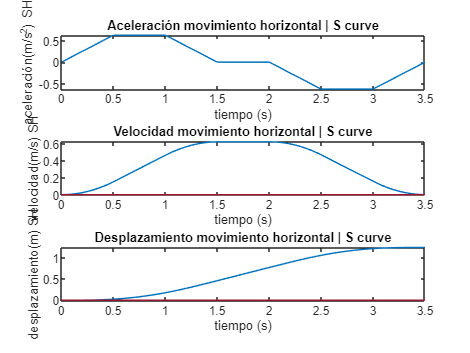

delta=0.01;
m=1.25;
t=linspace(0,3.5,length(adef));
ah=(m*ctramp(t)-m*ctramp(t-3.5/7)-m*ctramp(t-2*3.5/7)).*(t<3*3.5/7)...
    +(-1)*(m*ctramp(t-4*3.5/7)-m*ctramp(t-(5*3.5/7))-m*ctramp(t-(6*3.5/7))).*(t>4*3.5/7);
subplot(3,1,1)
plot(t,ah)
title('Aceleración movimiento horizontal | S curve')
xlabel('tiempo (s)')
ylabel('aceleración(m/s^2) SH')

vh=zeros(length(ah));
r=0;
for i=1:length(vh)
    index=find(t<=r);
    vh(i) = delta*sum(ah(index));
    r=r+delta;
end
subplot(3,1,2)
plot(t,vh)
title('Velocidad movimiento horizontal | S curve')
xlabel('tiempo (s)')
ylabel('velocidad(m/s) SH')

sh=zeros(length(ah));
r=0;
for i=1:length(sh)
    index=find(t<=r);
    sh(i) = delta.*sum(vh(index));
    r=r+delta;
end
subplot(3,1,3)
plot(t,sh)
title('Desplazamiento movimiento horizontal | S curve')
xlabel('tiempo (s)')
ylabel('desplazamiento(m) SH')


%{
Perfil de fuerza 
masa=366.7;
fH=a*masa;

plot(t,fH)
title('Perfil de fuerza Horizontal')
xlabel('tiempo (s)')
ylabel('fuerza (N) S')

%Perfil de torque 
torqueH=masa*9.81*s;
plot(t,torqueH)
title('Perfil de torque Horizontal')
xlabel('tiempo (s)')
ylabel('torque (N m) S')
%}

# Pérfiles de fuerza elevación 

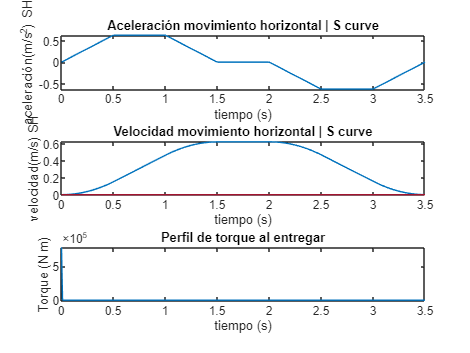

%Estimaciones iniciales
masac=366.7;
densidadB=2.69/10/10/10;
masab=densidadB*130*130*20; %suposición de la bandeja
t=linspace(0,3.5,length(adef));

%Tensión en la cuerda 

N=masac*(adef+9.81);
T=masab*(adef+9.81)+N;

plot(t,T)
title('Perfil de Tensión en el cable')
xlabel('tiempo (s)')
ylabel('Fuerza (N)')

%Torque en la base 
Mb=N*1.22+masab*9.81*3/4*1.22;

plot(t,Mb)
title('Perfil de torque en la base')
xlabel('tiempo (s)')
ylabel('Torque (N m)')

%Fuerza de las horquillas
ue=0.6;
Ft=masac*ah+ue*N;
plot(t,Ft)
title('Perfil de fuerza de las horquillas')
xlabel('tiempo (s)')
ylabel('Fuerza (N)')

%Torque en la entrega
Me=N*sh;
plot(t,Me)
title('Perfil de torque al entregar')
xlabel('tiempo (s)')
ylabel('Torque (N m)')